files = dir("performance_data/*_perform.csv")

files = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


f = 'characteristic_googlenet_25_perform.csv'

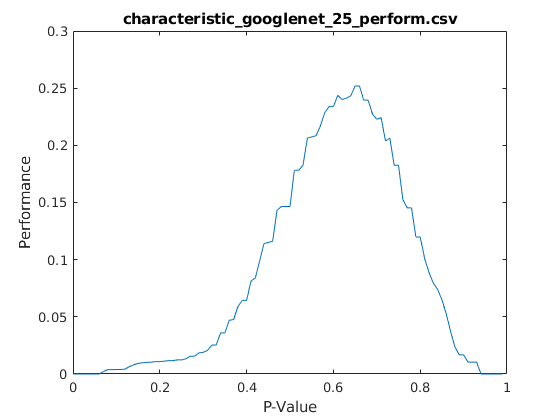

f = 'characteristic_perform.csv'

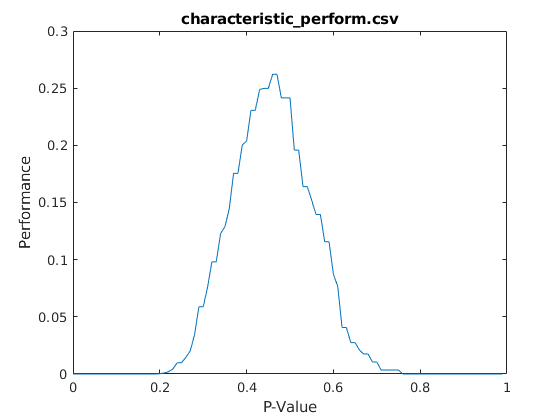

f = 'characteristic_resnext_25_perform.csv'

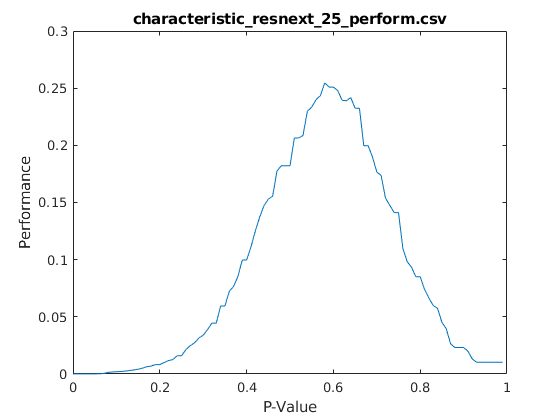

f = 'direct_googlenet_perform.csv'

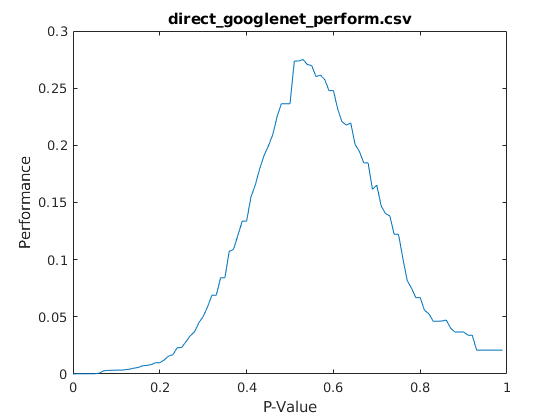

f = 'direct_perform.csv'

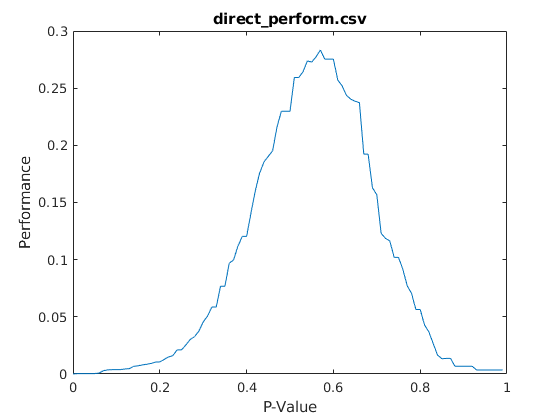


for i = 1:length(files)
    f = files(i).name
    figure;
    P = readmatrix("performance_data/"+f)';
    plot(P(:,1), P(:,2));
    xlabel("P-Value");
    ylabel("Performance");
    title(f, "Interpreter","none");
end

files = dir("edibility_data/*_perform.csv")

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


f = 'characteristic_ed_perform.csv'

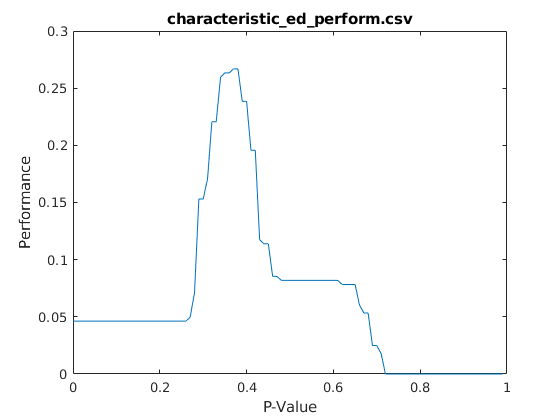

f = 'characteristic_googlenet_25_ed_perform.csv'

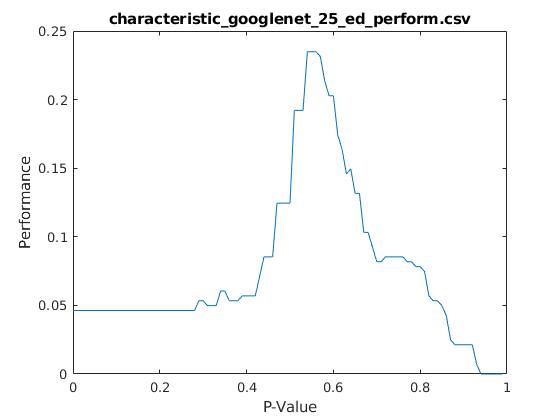

f = 'characteristic_resnext_25_ed_perform.csv'

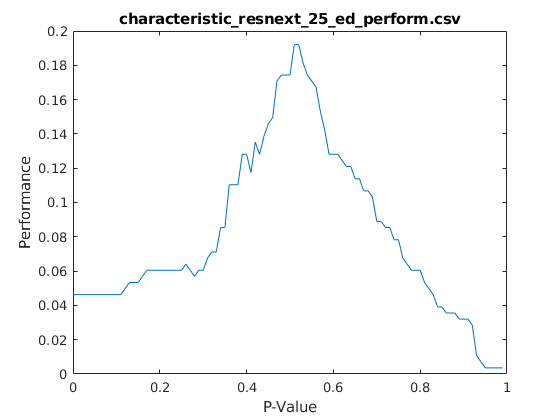

f = 'direct_ed_perform.csv'

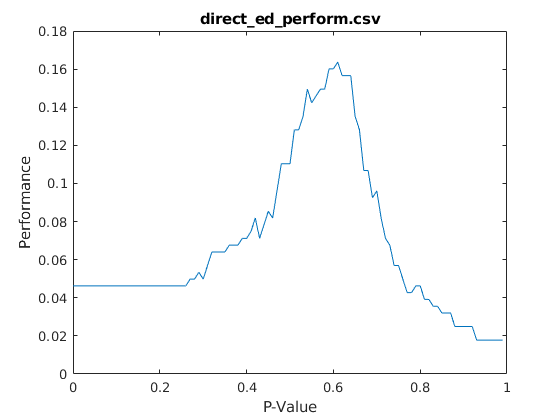


for i = 1:length(files)
    f = files(i).name
    figure;
    P = readmatrix("edibility_data/"+f)';
    plot(P(:,1), P(:,2));
    xlabel("P-Value");
    ylabel("Performance");
    title(f, "Interpreter","none");
end